#                                                 **滤波3**

*作者：张群伟	南昌航空大学信息工程学院自动化系*

*日期：2017年5月10日*

*下载链接：*[github](https://github.com/zhangqunwei/-Matlab-.git)

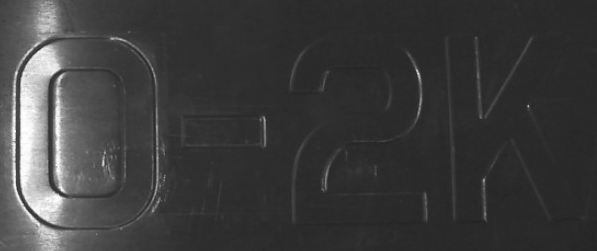

                                                                            （图LBimage3）

**1.设计内容：**

        对给定的图像LBimage3对图像进行滤波，去除光照影响，再进行二值化处理，得到较完整的数字和符号。

**2.设计要求：**

        １）可用ｍａｔｌａｂ或ＶＣ＋＋等语言编程，用ｍａｔｌａｂ编程时，设计中除了读写、显示、

数据类型转换等函数外以外，其它主要功能函数需自己编写。

        ２）所有设计内容要在一个主程序中运行实现，分步骤实现设计要求。

        ３）设计报告中需要分析影响结果的多种因素。

# 主程序：

**1.读取并显示原图**

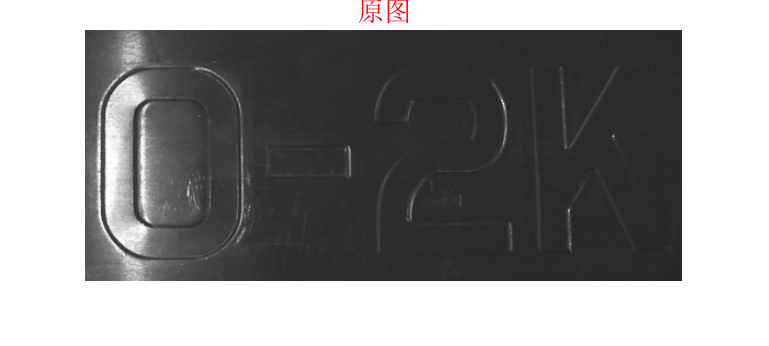

X_src=imread('LBimage3.bmp');
imshow(X_src);title('\fontsize{20}\color{red}原图');

**2.模糊增强**

% 对图像进行全局模糊增强
X_fuzzy=myfuzzy(X_src);

未定义与 'double' 类型的输入参数相对应的函数 'myfuzzy'。


% 对数字‘0’进行局部模糊增强
X_fuzzy(:,1:170)=myfuzzy(X_fuzzy(:,1:170));
imshow(X_fuzzy);title('\fontsize{20}\color{red}模糊增强');

**3.提取光照部分**

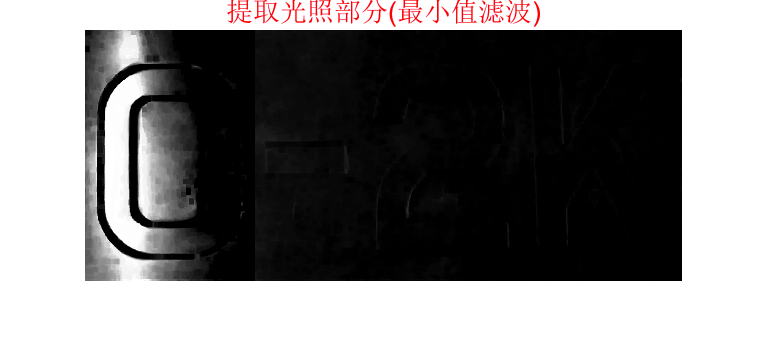

% 最小值滤波
X=double(X_fuzzy);     % 计算时需转为double型
X_min1=myfilter2('Minimum',X,5);        
imshow(X_min1);title('\fontsize{20}\color{red}提取光照部分(最小值滤波)');

**4.抑制噪声**

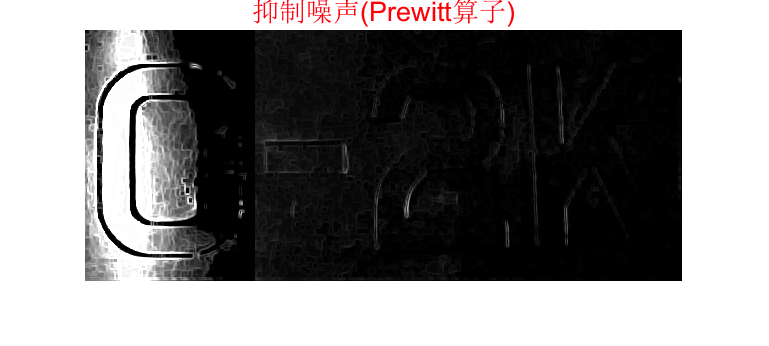

% 对图像全局使用Prewitt算子去噪
X_prewitt=myfilter2('Prewitt',X_min1);
% 对数字‘0’进行局部去噪
X_prewitt(:,1:170)=myfilter2('Prewitt',X_min1(:,1:170));
imshow(X_prewitt);title('\fontsize{20}\color{red}抑制噪声(Prewitt算子)');

**5.结果相减**

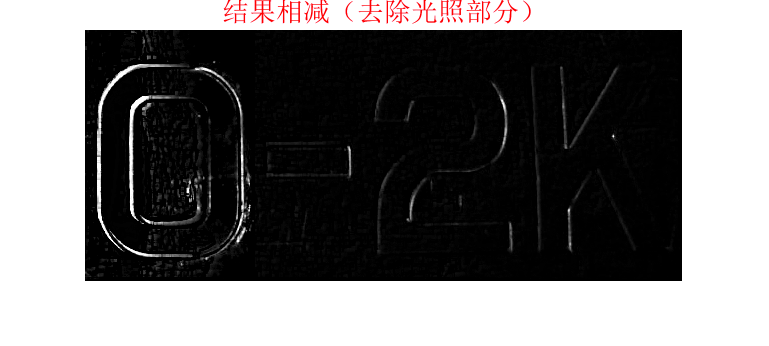

% 无光照图=模糊增强图-光照图
X_sub=X_fuzzy-uint8(X_prewitt);
imshow(uint8(X_sub));title('\fontsize{20}\color{red}结果相减（去除光照部分）');

**6.再次增强**

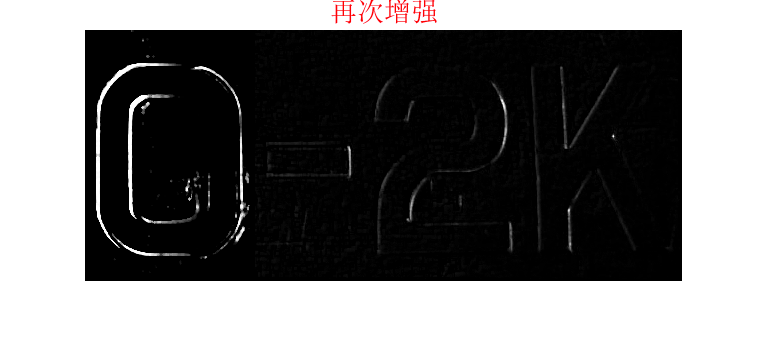

% 对数字‘0’进行模糊增强
X_sub(:,1:170)=myfuzzy(X_sub(:,1:170));
% 对数字‘0’进行去噪
X_sub(:,1:170)=myfilter2('Medium',X_sub(:,1:170),3);
imshow(uint8(X_sub));title('\fontsize{20}\color{red}再次增强');

**7.灰度拉伸**

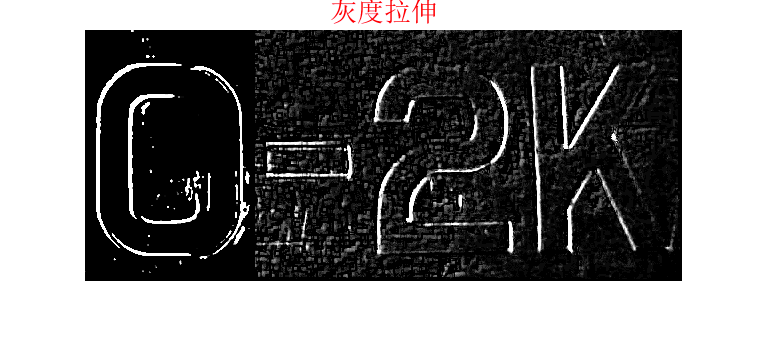

% 对去除光照后的图像进行线性灰度拉伸
NX_sub=11*X_sub;
imshow(uint8(NX_sub));title('\fontsize{20}\color{red}灰度拉伸');

## 二值化

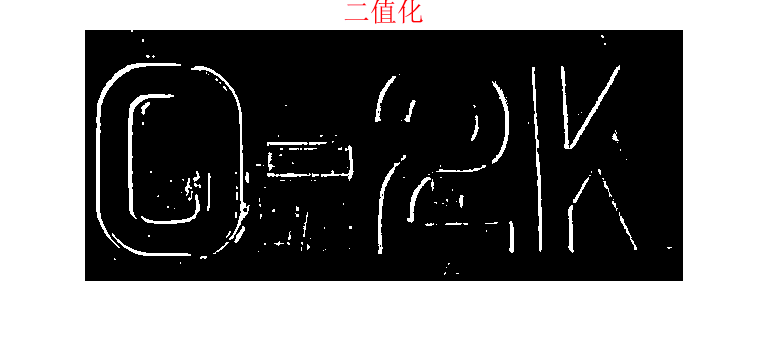

% 对图像进行分段二值化
% 对图像分两段进行不同阈值的二值化
% 对数字‘0’进行二值化
BW_left=myim2bw(NX_sub(:,1:170),0.99);
% 对数字‘0’右边进行二值化
BW_right=myim2bw(NX_sub(:,170:size(X,2)),0.6);
% 合成整幅图像
BW=[BW_left BW_right];
imshow(BW);title('\fontsize{20}\color{red}二值化');

% 显示原图，比较处理效果
imshow(X_src);title('\fontsize{20}\color{red}原图');